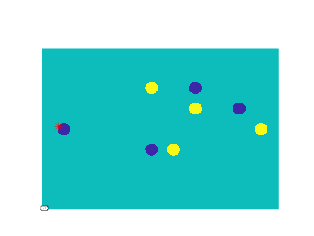

axis off
rectangle('Position', [-1 -1 11 8],'LineWidth', 0.125,'FaceColor',"#003518");
rectangle('Position', [0 0 9 6],'LineWidth', 0.125,'EdgeColor','white');
rectangle('Position', [0 0 9 6],'LineWidth', 0.125,'EdgeColor','white');
rectangle('Position', [0 0 4.5 6],'LineWidth', 0.125,'EdgeColor','white');
viscircles([4.5 3],0.75,'Color','white','LineWidth',0.125);
viscircles([7.5 3],0.075,'Color','white','LineWidth',0.125);
viscircles([1.5 3],0.075,'Color','white','LineWidth',0.125);
viscircles([4.5 3],0.075,'Color','white','LineWidth',0.125);
rectangle('Position', [0 1.5 1 3],'LineWidth', 0.125,'EdgeColor','white');
rectangle('Position', [8 1.5 1 3],'LineWidth', 0.125,'EdgeColor','white');
rectangle('Position', [0 0.5 2 5],'LineWidth', 0.125,'EdgeColor','white');
rectangle('Position', [7 0.5 2 5],'LineWidth', 0.125,'EdgeColor','white');
rectangle('Position', [-0.6 1.7 0.6 2.6],'LineWidth', 0.125,'EdgeColor','white');
rectangle('Position', [9 1.7 0.6 2.6],'LineWidth', 0.125,'EdgeColor','white');

players = [0,3;...
          4,2;...
          6,5;...
          8,4;...
          6,4;...
          5,2;...
          4,5;...
          9,3];
r=0.31

r = 0.3100

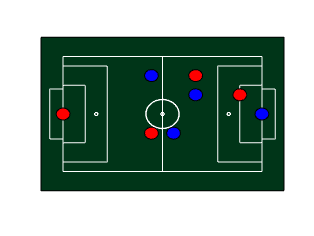

color = ['r','b'];
for idx = 1:8
    %[players(idx).pos(1)-r, players(idx).pos(2)-r];
    rectangle('Position',[players(idx,1)-r, players(idx,2)-r, 2*r, 2*r],'Curvature', [1,1], 'FaceColor',color(floor(idx/5)+1))
    %if norm(players(idx).vel)>0
    %    dir = players(idx).vel/norm(players(idx).vel);
    %    plot([players(idx).pos(1),players(idx).pos(1)+dir(1)*0.31],[players(idx).pos(2), players(idx).pos(2)+dir(2)*0.31],'LineWidth', 0.3,'Color','white');
    %end
end

fig = get(groot,'CurrentFigure');
F = getframe(fig);
[X, Map] = frame2im(F);
X=X(35:370,110:500,:)/255;

B = ones(size(X,1),size(X,2));
for i=1:size(X,1)
    for j=1:size(X,2)
        if X(i,j,1)==1 && X(i,j,2)==0 && X(i,j,3)==0
            B(i,j)=0;
        elseif X(i,j,1)==0 && X(i,j,2)==0 && X(i,j,3)==1
            B(i,j)=2;
        end
    end
end


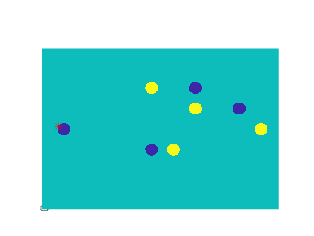

hold on
image(flip(B)*255/2)
plot(335*(players(1,1)+1)/12,390*(players(1,2)+1)/9,'r*')
hold off

red = B==0;
blue = B==2;